# H3

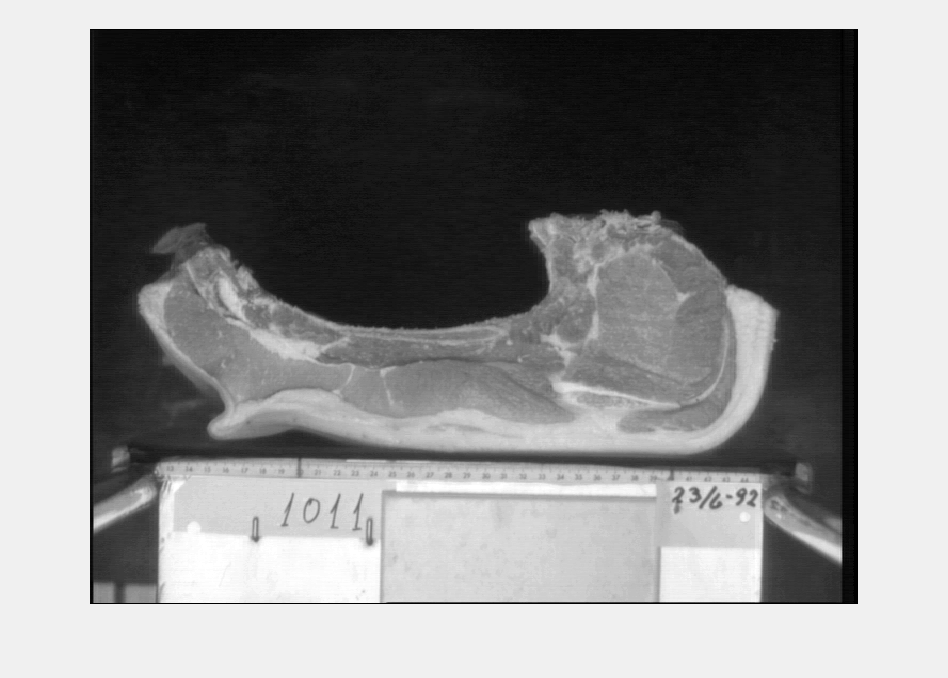

I = imread('F1011flb.bmp');
imshow(I);
rect = getrect; % obtenir rectangle

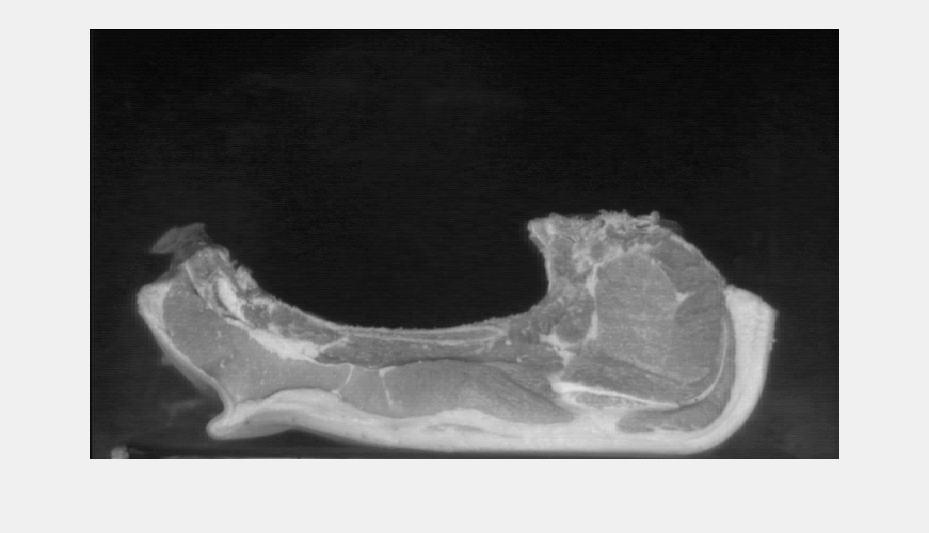

IC = imcrop(I,rect); % retallar
imshow(IC);

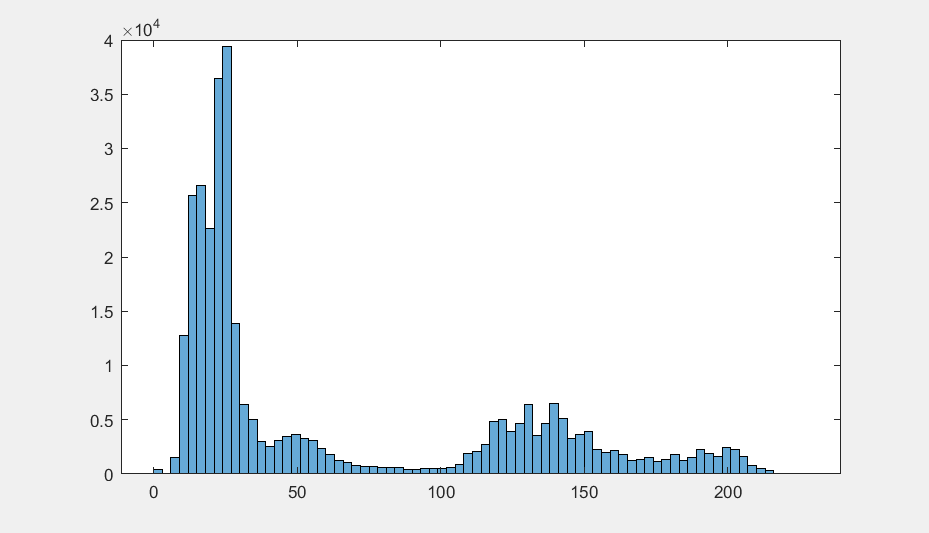

% treure el fons
histogram(IC);

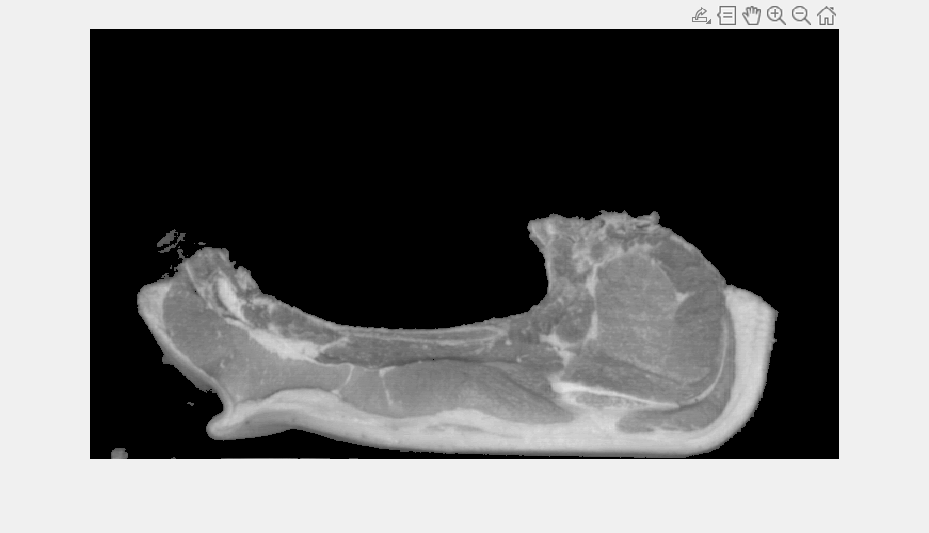

R = IC > 80;
R = IC .* uint8(R);
imshow(R);

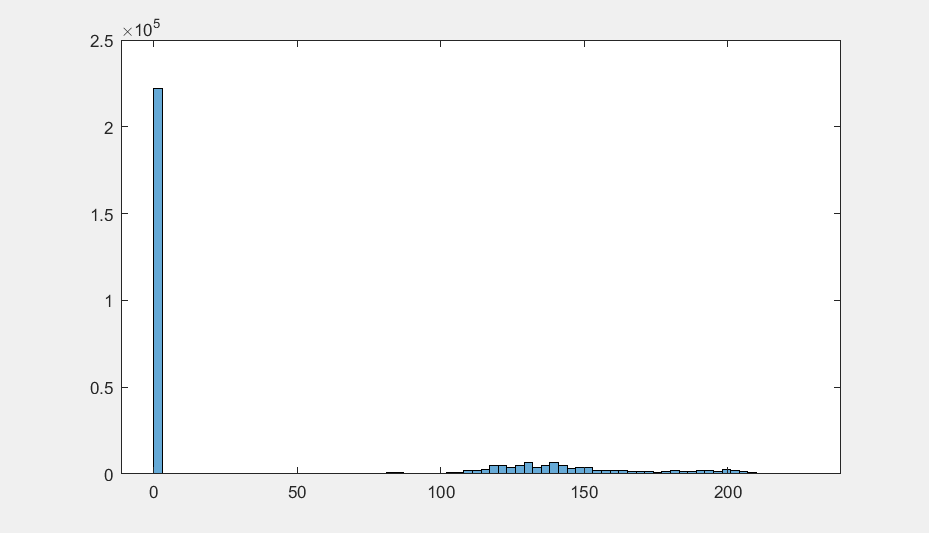

% calcular percentatge greix
CR = bwconncomp(R);
npixelsCR = cellfun(@numel,CR.PixelIdxList);
npixelsCR = sum(npixelsCR(1,:)); % número de píxels del tros de carn
histogram(R);

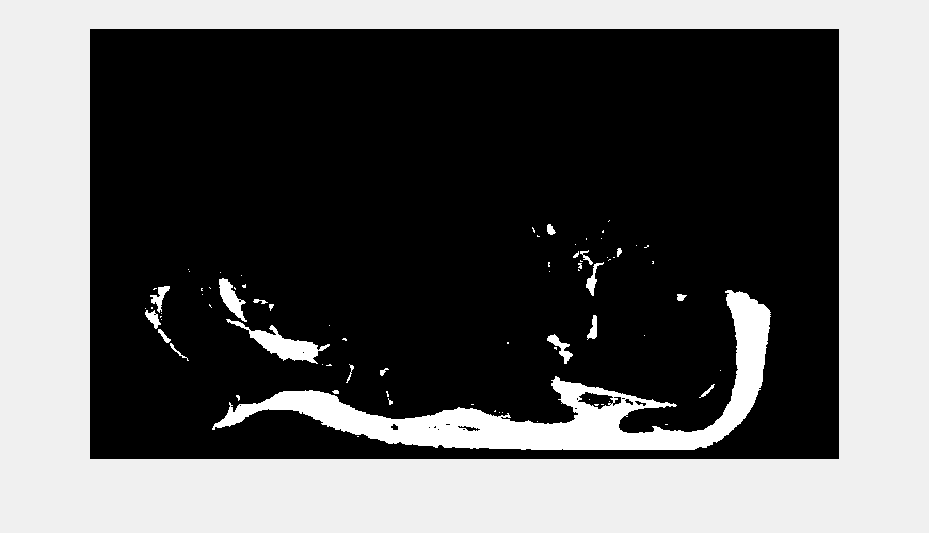

BW = R > 170;
imshow(BW);

CBW = bwconncomp(BW);
npixelsCBW = cellfun(@numel,CBW.PixelIdxList);
npixelsCBW = sum(npixelsCBW(1,:)); % número de píxels del greix
p = npixelsCBW/npixelsCR * 100

p = 22.1918

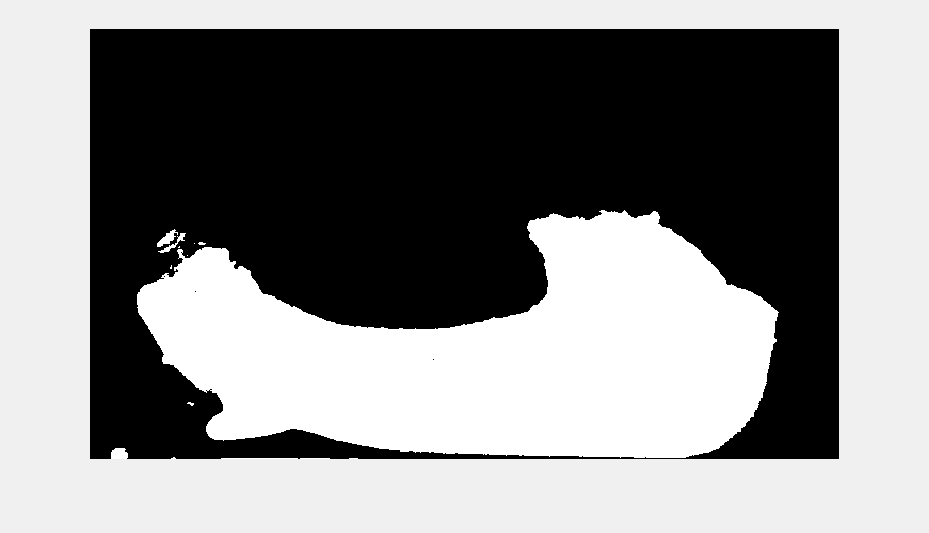

% calcular percentatge greix amb graythresh (no funciona)
t = graythresh(R);
BWG = R > t*256;
imshow(BWG);

CBWG = bwconncomp(BWG);
npixelsCBWG = cellfun(@numel,CBWG.PixelIdxList);
npixelsCBWG = sum(npixelsCBWG(1,:));
p2 = npixelsCBWG/npixelsCR * 100

p2 = 100